## Cell 1: Load Data & Plot NMSE vs SNR (dB)

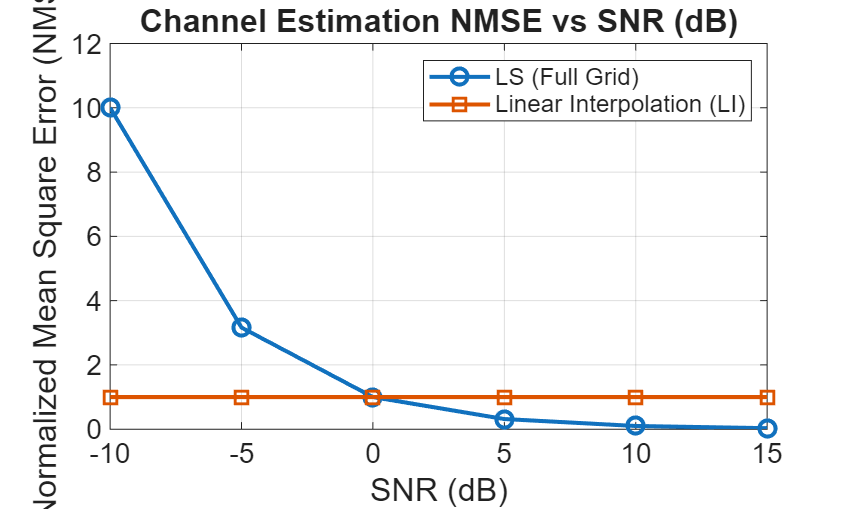

clc;

try
    results_dir = fileparts(matlab.desktop.editor.getActiveFilename);
catch
    results_dir = '';
end
if isempty(results_dir) || ~exist(results_dir, 'dir')
    results_dir = fileparts(mfilename('fullpath'));
end
if isempty(results_dir) || ~exist(results_dir, 'dir')
    results_dir = pwd;
end

dir_info = dir(results_dir);
snr_vec = [];
folder_names = {};

for k = 1:length(dir_info)
    if dir_info(k).isdir && ~strncmp(dir_info(k).name, '.', 1)
        fname = dir_info(k).name;
        snr_match = regexp(fname, '(-?\d+)\s*dB', 'tokens');
        if ~isempty(snr_match)
            val = str2double(snr_match{1}{1});
            snr_vec(end+1) = val; %#ok<AGROW>
            folder_names{end+1} = fname; %#ok<AGROW>
        end
    end
end

[snr_vec, sort_idx] = sort(snr_vec);
folder_names = folder_names(sort_idx);

num_snr = length(snr_vec);
avg_nmse_ls       = zeros(1, num_snr);
avg_nmse_li       = zeros(1, num_snr);
avg_nmse_prac     = zeros(1, num_snr);
avg_nmse_ls_pilot = zeros(1, num_snr);

avg_ssim_ls   = zeros(1, num_snr);
avg_ssim_li   = zeros(1, num_snr);
avg_ssim_prac = zeros(1, num_snr);

for k = 1:num_snr
    folder_path = fullfile(results_dir, folder_names{k});
    mat_files = dir(fullfile(folder_path, '*.mat'));
    if ~isempty(mat_files)
        mat_path = fullfile(folder_path, mat_files(1).name);
        data = load(mat_path);
        
        if isfield(data, 'nmse_ls'),       avg_nmse_ls(k)       = mean(data.nmse_ls, 'all'); end
        if isfield(data, 'nmse_li'),       avg_nmse_li(k)       = mean(data.nmse_li, 'all'); end
        if isfield(data, 'nmse_prac'),     avg_nmse_prac(k)     = mean(data.nmse_prac, 'all'); end
        if isfield(data, 'nmse_ls_pilot'), avg_nmse_ls_pilot(k) = mean(data.nmse_ls_pilot, 'all'); end
        
        if isfield(data, 'ssim_ls'),   avg_ssim_ls(k)   = mean(data.ssim_ls, 'all'); end
        if isfield(data, 'ssim_li'),   avg_ssim_li(k)   = mean(data.ssim_li, 'all'); end
        if isfield(data, 'ssim_prac'), avg_ssim_prac(k) = mean(data.ssim_prac, 'all'); end
    end
end

figure;
plot(snr_vec, avg_nmse_ls, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'LS (Full Grid)');
hold on;
plot(snr_vec, avg_nmse_li, '-s', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Linear Interpolation (LI)');

hold off;

grid on;
set(gca, 'FontSize', 14);
xlabel('SNR (dB)', 'FontSize', 16);
ylabel('Normalized Mean Square Error (NMSE)', 'FontSize', 16);
title('Channel Estimation NMSE vs SNR (dB)', 'FontSize', 16);
legend('Location', 'northeast', 'FontSize', 12);

## Cell 2: Plot SSIM vs SNR (dB)

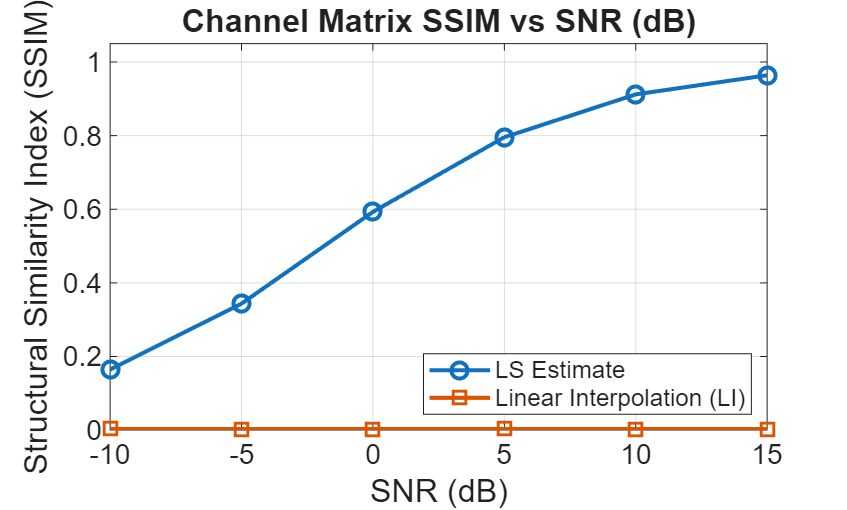

figure;
plot(snr_vec, avg_ssim_ls, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'LS Estimate');
hold on;
plot(snr_vec, avg_ssim_li, '-s', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Linear Interpolation (LI)');

hold off;

grid on;
set(gca, 'FontSize', 14);
xlabel('SNR (dB)', 'FontSize', 16);
ylabel('Structural Similarity Index (SSIM)', 'FontSize', 16);
title('Channel Matrix SSIM vs SNR (dB)', 'FontSize', 16);
legend('Location', 'southeast', 'FontSize', 12);
ylim([0, 1.05]);